Extract band power features

%% Step 5: SVM Classification
clear all; close all; clc;
basePath = '/Users/kandulasatwika/Desktop/400_BCI_MATLAB';
% Load combined data
load(fullfile(basePath, 'Outputs', 'Filtered data', 'combined_epochs.mat'));
sfreq = 160;
% Extract features
disp('Extracting features...');

Extracting features...


feat_left  = extract_bandpower(all_left,  sfreq);
feat_right = extract_bandpower(all_right, sfreq);
feat_rest  = extract_bandpower(all_rest,  sfreq);
disp(['Feature shape left: ',  num2str(size(feat_left))]);

Feature shape left: 230  128


disp(['Feature shape right: ', num2str(size(feat_right))]);

Feature shape right: 220  128


disp(['Feature shape rest: ',  num2str(size(feat_rest))]);

Feature shape rest: 420  128


%Usually, the rows represent epochs/trials, and the columns represent extracted features.

%% Balance dataset and train SVM
n = 220; % minimum class size
% Balance all classes
rng(42); % for reproducibility
%randomly selects 220 rows..
idx_left  = randperm(size(feat_left,1),  n);
idx_right = randperm(size(feat_right,1), n);
idx_rest  = randperm(size(feat_rest,1),  n);
%combines all the selected features
X = [feat_left(idx_left,:); feat_right(idx_right,:); feat_rest(idx_rest,:)];
%x is features(660)
y = [ones(n,1); 2*ones(n,1); 3*ones(n,1)];
%y lables(669)[1->left,2->right,3->rest]

% Split train and test — 80/20
cv = cvpartition(y, 'HoldOut', 0.2);
X_train = X(cv.training,:);
y_train = y(cv.training);
X_test  = X(cv.test,:);
y_test  = y(cv.test);

disp(['Training samples: ', num2str(sum(cv.training))]);

Training samples: 528


disp(['Testing samples: ',  num2str(sum(cv.test))]);

Testing samples: 132



% Train SVM
disp('Training SVM...');

Training SVM...


svm_model = fitcecoc(X_train, y_train);

% Test SVM
y_pred = predict(svm_model, X_test);
accuracy = sum(y_pred == y_test) / length(y_test) * 100;
disp(['Accuracy: ', num2str(accuracy), '%']);

Accuracy: 39.3939%


% Convert labels to categorical
class_names = {'Left', 'Right', 'Rest'};
y_cat = categorical(y, [1,2,3], class_names);
y_train_cat = y_cat(cv.training);
y_test_cat  = y_cat(cv.test);

% Train SVM with categorical labels
svm_model = fitcecoc(X_train, y_train_cat);
y_pred_cat = predict(svm_model, X_test);

% Accuracy
accuracy = sum(y_pred_cat == y_test_cat) / length(y_test_cat) * 100;
disp(['Accuracy: ', num2str(accuracy), '%']);

Accuracy: 39.3939%


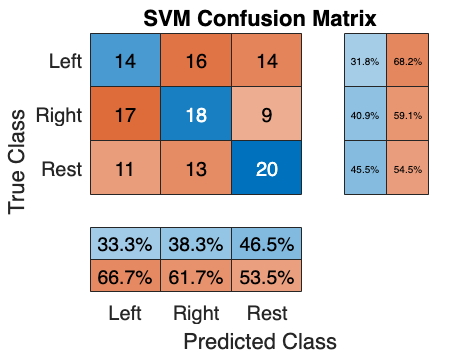


% Confusion matrix with correct labels
figure;
confusionchart(y_test_cat, y_pred_cat, ...
    'RowSummary', 'row-normalized', ...
    'ColumnSummary', 'column-normalized');
title('SVM Confusion Matrix');
saveas(gcf, fullfile(basePath, 'Outputs', 'Plots', 'svm_confusion_matrix.png'));

disp('Confusion matrix saved!');

Confusion matrix saved!



[y_pred_conf, scores] = predict(svm_model, X_test);
%% Confidence threshold approach
commands = cell(length(y_test_cat), 1);
for i = 1:length(scores)
    max_conf = max(scores(i,:));
    
    % Less negative = more confident
    % If max score is below -0.5, not confident enough → REST
    if max_conf < -0.5
        commands{i} = 'REST';
    elseif y_pred_conf(i) == 'Left'
        commands{i} = 'LEFT';
    elseif y_pred_conf(i) == 'Right'
        commands{i} = 'RIGHT';
    else
        commands{i} = 'REST';
    end
end

% Count commands
left_count  = sum(strcmp(commands, 'LEFT'));
right_count = sum(strcmp(commands, 'RIGHT'));
rest_count  = sum(strcmp(commands, 'REST'));
total = length(commands);

fprintf('LEFT:  %d (%.1f%%)\n', left_count,  left_count/total*100);

LEFT:  39 (29.5%)


fprintf('RIGHT: %d (%.1f%%)\n', right_count, right_count/total*100);

RIGHT: 44 (33.3%)


fprintf('REST:  %d (%.1f%%)\n', rest_count,  rest_count/total*100);

REST:  49 (37.1%)


% Save SVM model and commands
save(fullfile(basePath, 'Outputs', 'Filtered data', 'svm_model.mat'), ...
    'svm_model', 'commands');
disp('Model saved!');

Model saved!


function features = extract_bandpower(data, sfreq)
    [n_channels, ~, n_epochs] = size(data);
    features = zeros(n_epochs, n_channels * 2);
    %a 2D matrix--->each channel 2 features (mu power and beta power)
    %277 × 128(epochs and features per epoch)
    for e = 1:n_epochs
        feat = [];
        for c = 1:n_channels
            %goes through each channel
            signal = data(c,:,e);
            %gives one EEG signal segment from one channel and one epoch.
            [psd, freqs] = pwelch(signal, [], [], [], sfreq);
            %pwelch tells us how much energy the EEG signal has at different frequencies.
            mu   = mean(psd(freqs>=8  & freqs<=12));
            beta = mean(psd(freqs>=13 & freqs<=30));
            feat = [feat, mu, beta];
        end
        features(e,:) = feat;
        %So one row of features represents one epoch.
    end
end